VA Comparison to Literature

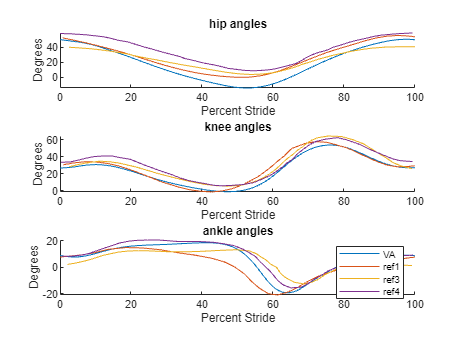

ref_folder = dir("MVCorrViconFiles/Reference strides/");
ref_struct = struct("dontuse", "dontuse");

ref_list = {};
joint_list = {};

for i = 1:numel(ref_folder)
    ref_file = ref_folder(i);
    if ref_file.bytes > 0
        name_ = split(ref_file.name, '.');
        name_ = split(name_{1}, '_');

        ref_list{end+1} = name_{1};
        joint_list{end+1} = name_{2};

        data_ = load(ref_file.name);

        ref_struct.(name_{1}).(name_{2}) = data_;
    end
end

ref_list = unique(ref_list);
joint_list = {"hip", "knee", "ankle"};%unique(joint_list);
ref_struct = rmfield(ref_struct, "dontuse");

fn = fields(packed_data);
sizes = packed_data.(fn{1}).stride_avg_l;
[x, y] = size(sizes{1});
d = 2 * length(fields(packed_data));
strides_avg_all = zeros(d, x, y);

for s = 1:length(fields(packed_data))
    subj_fields = fields(packed_data);
    subj = subj_fields{s};

    strides_avg_l = packed_data.(subj).stride_avg_l;
    strides_avg_l = strides_avg_l{1};
    strides_avg_r = packed_data.(subj).stride_avg_r;
    strides_avg_r = strides_avg_r{1};

    strides_avg_all(2*s-1, :, :) = strides_avg_l;
    strides_avg_all(2*s, :, :) = strides_avg_r;
end

strides_avg_all_mean = squeeze(mean(strides_avg_all, 1));

comparison_rmse = zeros(length(joint_list), length(ref_list));
comparison_mape = zeros(length(joint_list), length(ref_list));

strides_index = [3, 4, 5];
for j = 1:length(joint_list)
    subplot(3, 1, j)
    title(joint_list{j} + " angles")
    hold on

    va_strides = strides_avg_all_mean(strides_index(j), :);
    plot(linspace(0, 100, 100), va_strides, 'DisplayName', 'VA')

    for n = 1:length(ref_list)
        data_ = ref_struct.(ref_list{n}).(joint_list{j});
        interp_data_ = interp1(data_(:, 1), data_(:, 2), linspace(0, 100, 100), "linear", "extrap");

        comparison_rmse(j, n) = rmse(va_strides, interp_data_);
        comparison_mape(j, n) = mape(va_strides, interp_data_);

        plot(data_(:, 1), data_(:, 2), 'DisplayName', ref_list{n})
    end
    xlabel("Percent Stride")
    ylabel("Degrees")
    xlim([0, 100])
end
legend("Interpreter", "none")

rmse_table = table;
rmse_table.joints = joint_list';
rmse_table.ref1 = comparison_rmse(1, :)';
rmse_table.ref2 = comparison_rmse(2, :)';
rmse_table.ref3 = comparison_rmse(3, :)';

mape_table = table;
mape_table.joints = joint_list';
mape_table.ref1 = comparison_mape(1, :)';
mape_table.ref2 = comparison_mape(2, :)';
mape_table.ref3 = comparison_mape(3, :)';

rmse_table

rmse_table = 3×4 table
      joints        ref1      ref2      ref3 
    ___________    ______    ______    ______

    {["hip"  ]}    8.9097    5.4869    6.8166
    {["knee" ]}    10.824    7.1061    6.2029
    {["ankle"]}    17.544    8.4129    3.0432


mape_table

mape_table = 3×4 table
      joints        ref1      ref2      ref3 
    ___________    ______    ______    ______

    {["hip"  ]}    392.78    59.253    292.52
    {["knee" ]}    89.296    33.209    177.65
    {["ankle"]}    76.934    37.055    32.267
